# The Training Unit 2: NEDC Simulation

Fink Lucas / Teichtmeister Marcus, 08.10.2025

## MATLAB Setup

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Loading and processing of existing data

Storing the parameters of the vehicle under investigation

VEHICLE_PARAMETER.VEHICLE_WEIGHT.data          = struct('value', 1250, 'unit', 'kg');
VEHICLE_PARAMETER.E_MOTOR_POWER.data           = struct('value', 60,   'unit', 'kW');
VEHICLE_PARAMETER.BATTERY_CAPACITY.data        = struct('value', 22,   'unit', 'kWh');
VEHICLE_PARAMETER.TRANSMISSION_EFFICIENCY.data = struct('value', 96,   'unit', '%');
VEHICLE_PARAMETER.ENGINE_EFFICIENCY.data       = struct('value', 94,   'unit', '%');
VEHICLE_PARAMETER.INVERTER_EFFICIENCY.data     = struct('value', 97,   'unit', '%');
VEHICLE_PARAMETER.BATTERY_EFFICIENCY.data      = struct('value', 90,   'unit', '%');
VEHICLE_PARAMETER.CHARGER_EFFICIENCY.data      = struct('value', 94,   'unit', '%');

Next, the collected data "MotorSpeed", "Distance" and "VehicleSpeed" will be read out from the Data.xls File. The data is merged into a table with 3 columns. This is handled by the MATLAB function "importExcelData" which gets the filename as a parameter and returns the extracted data table.

The displayed size of the table is: 2401x3

filename_data = 'Data.xls';
dataTable = importExcelData(filename_data)

dataTable = 2401×3 table
    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]
    _________________    ___________    __________________
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                 0         
            0                 0                

Furthermore, a second MATLAB function "importTorqueData" is implemented which stores the torque data in the already existing data table and also includes the sampling time as the first column in the table.

The object **Motor_Torque i**ncludes 2401 data points of motor torque values over time. The dataset provides both the torque data and the corresponding time vector, as well as additional metadata for time, data, and quality. The datapoints of the time vector suggests that the data was recorded with consistent sampling. The metadata also indicates that NaN values are treated as missing data.

filename_torque = 'Torque.mat';
dataTable = importTorqueData(filename_torque, dataTable)

dataTable = 2401×5 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]
    ________________    _________________    ___________    __________________    __________
            0                   0                 0                 0                 0     
          0.5                   0                 0                 0                 0     
            1                   0                 0                 0                 0     
          1.5                   0                 0                 0                 0     
            2                   0                 0                 0                 0     
          2.5                   0                 0                 0                 0     
            3                   0                 0          

The imported torque time series and other artifacts are removed from the workspace.

clearvars -except dataTable VEHICLE_PARAMETER;

### Presenting the results

In the next four plots, the variables MotorSpeed, Distance, VehicleSpeed and and Torque are plotted over the sampled time period.

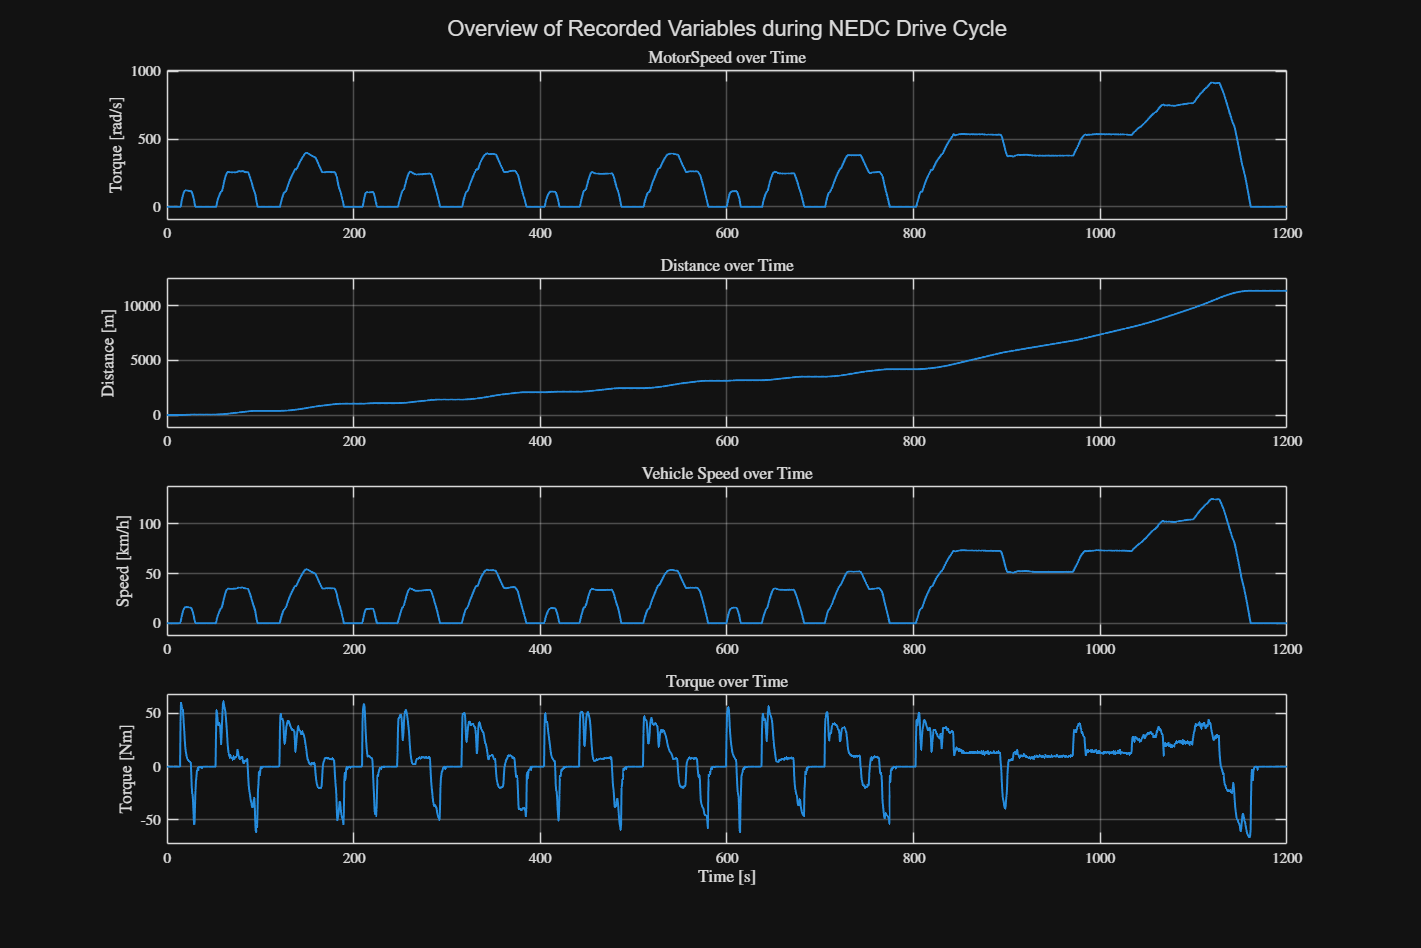

time = dataTable{:,1};              
motor_speed = dataTable{:,2};             
distance = dataTable{:,3};              
vehicle_speed = dataTable{:,4};             
torque = dataTable{:,5};              

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(4, 1)    

% 1. Plot: MotorSpeed
nexttile
plot(time, motor_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(motor_speed)-0.1*max(motor_speed), max(motor_speed)+0.1*max(motor_speed)])
title('MotorSpeed over Time')
ylabel('Torque [rad/s]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 2. Plot: Distance
nexttile
plot(time, distance, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(distance)-0.1*max(distance), max(distance)+0.1*max(distance)])
title('Distance over Time')
ylabel('Distance [m]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 3. Plot VehicleSpeed
nexttile
plot(time, vehicle_speed, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(vehicle_speed)-0.1*max(vehicle_speed), max(vehicle_speed)+0.1*max(vehicle_speed)])
title('Vehicle Speed over Time')
ylabel('Speed [km/h]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

% 4.Plot: Torque
nexttile
plot(time, torque, 'LineWidth', 1.2)
grid on
axis([min(time), max(time), min(torque)-0.1*max(torque), max(torque)+0.1*max(torque)])
title('Torque over Time')
xlabel('Time [s]')
ylabel('Torque [Nm]')
set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

clearvars -except dataTable VEHICLE_PARAMETER;
sgtitle('Overview of Recorded Variables during NEDC Drive Cycle')

## Performing Calculations / Conversions on the data table

The motor speed is converted from rad/s to rpm and stored in a separate column in the data table.

Motor_RPM = 30/pi .* dataTable.("MotorSpeed[rad/s]");
dataTable = [dataTable, table(Motor_RPM,VariableNames="MotorSpeed[rpm]")]

dataTable = 2401×6 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]
    ________________    _________________    ___________    __________________    __________    _______________
            0                   0                 0                 0                 0                0       
          0.5                   0                 0                 0                 0                0       
            1                   0                 0                 0                 0                0       
          1.5                   0                 0                 0                 0                0       
            2                   0                 0                 0                 0            

Next,  the mean vehicle speed in km/h is calculated and stored in a new structure. 

AVG_VELOCITY = 1/dataTable.('sampling_time[s]')(2401) * dataTable.("Distance[m]")(2401) * 3.6

AVG_VELOCITY =     34.1392e+000

VEHICLE_CHAR.MEAN_VEL.data        = struct('value', AVG_VELOCITY, 'unit', 'km/h');

The mechanical power demanded by the vehicle can be calculated with the formula: $P_{\textrm{mech}} =T\cdot \omega$. It is then also stored in the data table. 

P_mech = dataTable.("MotorSpeed[rad/s]") .* dataTable.('Torque[Nm]');
dataTable = [dataTable, table(P_mech, VariableNames="P_mech[W]")]

dataTable = 2401×7 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]
    ________________    _________________    ___________    __________________    __________    _______________    _________
            0                   0                 0                 0                 0                0               0    
          0.5                   0                 0                 0                 0                0               0    
            1                   0                 0                 0                 0                0               0    
          1.5                   0                 0                 0                 0                0        

The motor has a power of 60 kW (VEHICLE_PARAMETER.E_MOTOR_POWER.data), whereas the maximum calculated mechanical power is 39 kW. Thus, the motor is sufficiently.

P_mech_max = max(dataTable.('P_mech[W]'))

P_mech_max =     39.5518e+003

VEHICLE_PARAMETER.E_MOTOR_POWER.data

ans = struct with fields:
    value: 60.0000e+000
     unit: 'kW'

The mechanical power demand is integrated over time to obtain the corresponding instantaneous energy (in joules), which was added to the results table with the correct unit. Then, the instantaneous energies at different levels of the efficiency chain are calculated, ignoring energy flow direction for a first estimation. Finally, the total energy losses at each stage of the efficiency chain are computed and stored.

time = dataTable{:, "sampling_time[s]"};

E_mech = cumtrapz(time, P_mech);
dataTable =  [dataTable, table(E_mech, VariableNames="E_mech[J]")];
E_Motor_out = dataTable{:,"E_mech[J]"};
E_Transmission = E_Motor_out;  % the Output Energy from the Motor is the Energy received by the Transmission

% Efficiencies
EFFICIENCY.ETA_TRANS     = double(VEHICLE_PARAMETER.TRANSMISSION_EFFICIENCY.data.value)/100;
EFFICIENCY.ETA_MOTOR     = double(VEHICLE_PARAMETER.ENGINE_EFFICIENCY.data.value)/100;
EFFICIENCY.ETA_INVERTER  = double(VEHICLE_PARAMETER.INVERTER_EFFICIENCY.data.value)/100;
EFFICIENCY.ETA_BATTERY    = double(VEHICLE_PARAMETER.BATTERY_EFFICIENCY.data.value)/100;


% Calculating the Energy Flow
E_Wheel    = E_Transmission .* EFFICIENCY.ETA_TRANS;
E_Motor_in = E_Transmission ./ EFFICIENCY.ETA_MOTOR;
E_Inverter = E_Motor_in     ./ EFFICIENCY.ETA_INVERTER;
E_Battery  = E_Inverter     ./ EFFICIENCY.ETA_BATTERY;

% adding to data Table
dataTable =  [dataTable, table(E_Wheel, VariableNames="E_Wheel[J]"), table(E_Motor_in, VariableNames="E_Motor_in[J]"), ...
    table(E_Inverter, VariableNames="E_Inverter[J]"), table(E_Battery, VariableNames="E_Battery[J]")];

%Calculating the complete energy loss at each part of the efficiency chain
E_Loss_Transmission = E_Motor_out(end) - E_Wheel(end);
E_Loss_Motor        = E_Motor_in(end)  - E_Motor_out(end);
E_Loss_Inverter     = E_Inverter(end)  - E_Motor_in(end);
E_Loss_Battery      = E_Battery (end)  - E_Inverter(end);
E_Loss_Total         = E_Loss_Battery + E_Loss_Inverter + E_Loss_Motor + E_Loss_Transmission;

% storing the energy losses in the data structure
VEHICLE_CHAR.BATTERY_LOSS.data           = struct('value', E_Loss_Battery,      'unit', 'J');
VEHICLE_CHAR.INVERTER_LOSS.data          = struct('value', E_Loss_Inverter,     'unit', 'J');
VEHICLE_CHAR.MOTOR_LOSS.data             = struct('value', E_Loss_Motor,        'unit', 'J');
VEHICLE_CHAR.TRANSMISSION_LOSS.data      = struct('value', E_Loss_Transmission, 'unit', 'J');
VEHICLE_CHAR.TOTAL_LOSS.data             = struct('value', E_Loss_Total,        'unit', 'J');


### Presenting the results

In the first plot, the vehicle speed, motor speed and the average vehicle velocity is displayed. 

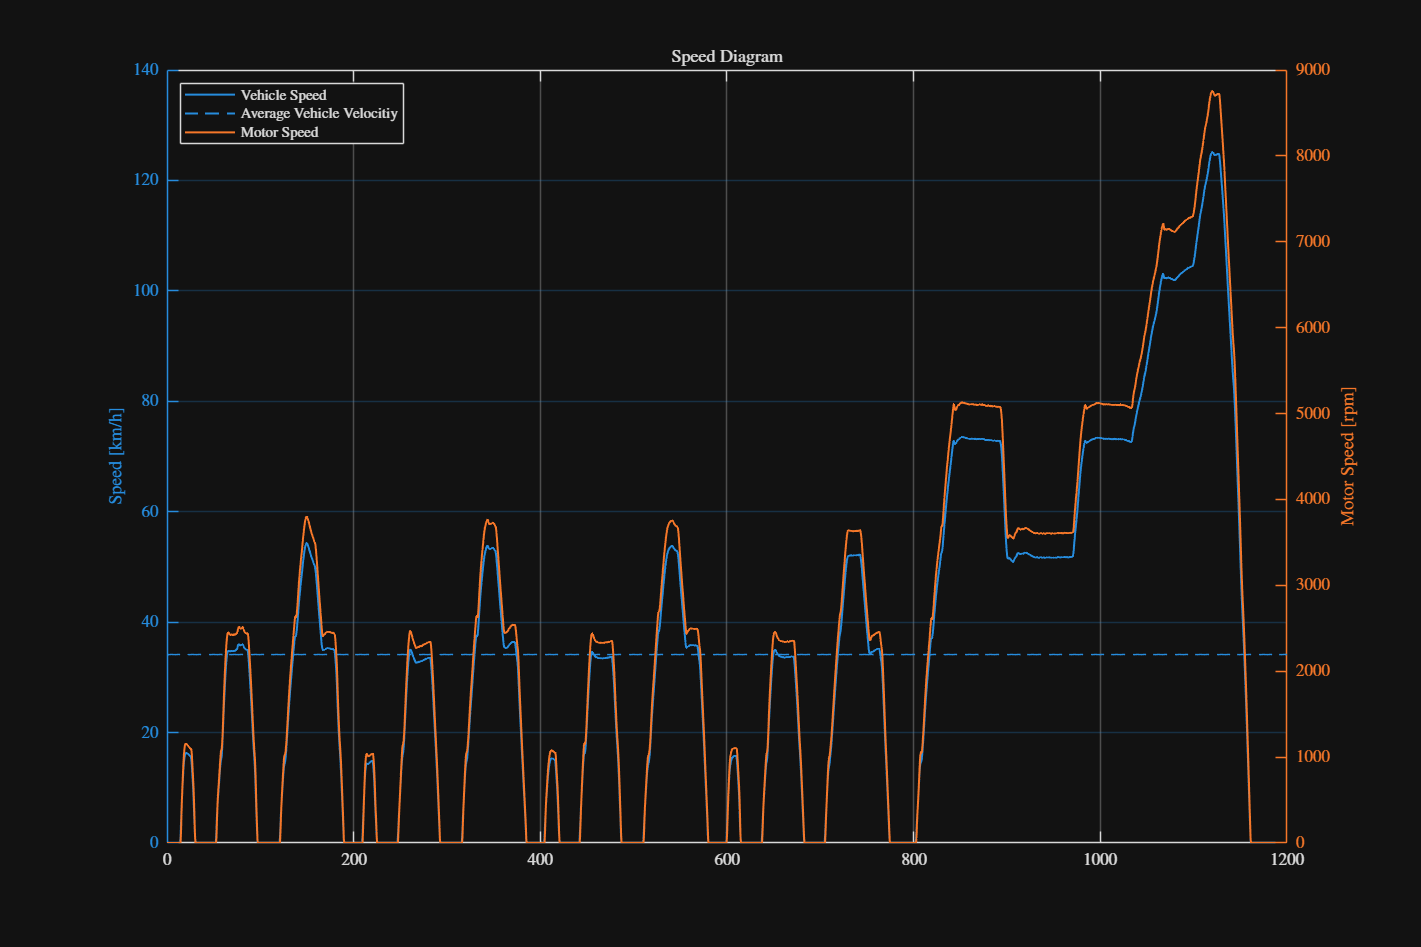

time = dataTable{:, "sampling_time[s]"};     
vehicle_speed = dataTable{:,"VehicleSpeed[km/h]"};
motor_RPM = dataTable{:, "MotorSpeed[rpm]"};

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(1, 1)    

% Vehicle Speed, Mean-Vehicle Speed, Motor Speed
nexttile
yyaxis left
plot(time, vehicle_speed, 'LineWidth', 1.2)
hold on
plot(time, AVG_VELOCITY*ones(size(time)), 'LineWidth', 1.2)
grid on
ylabel('Speed [km/h]')
yyaxis right
plot(time, motor_RPM, 'LineWidth', 1.2)
grid on
ylabel('Motor Speed [rpm]');

title('Speed Diagram')
legend('Vehicle Speed', 'Average Vehicle Velocitiy', 'Motor Speed', 'Location','northwest')

In the second plot, the mechanical power is plotted over time. Additionally, a dashed line indicates the maximum available power of the engine.

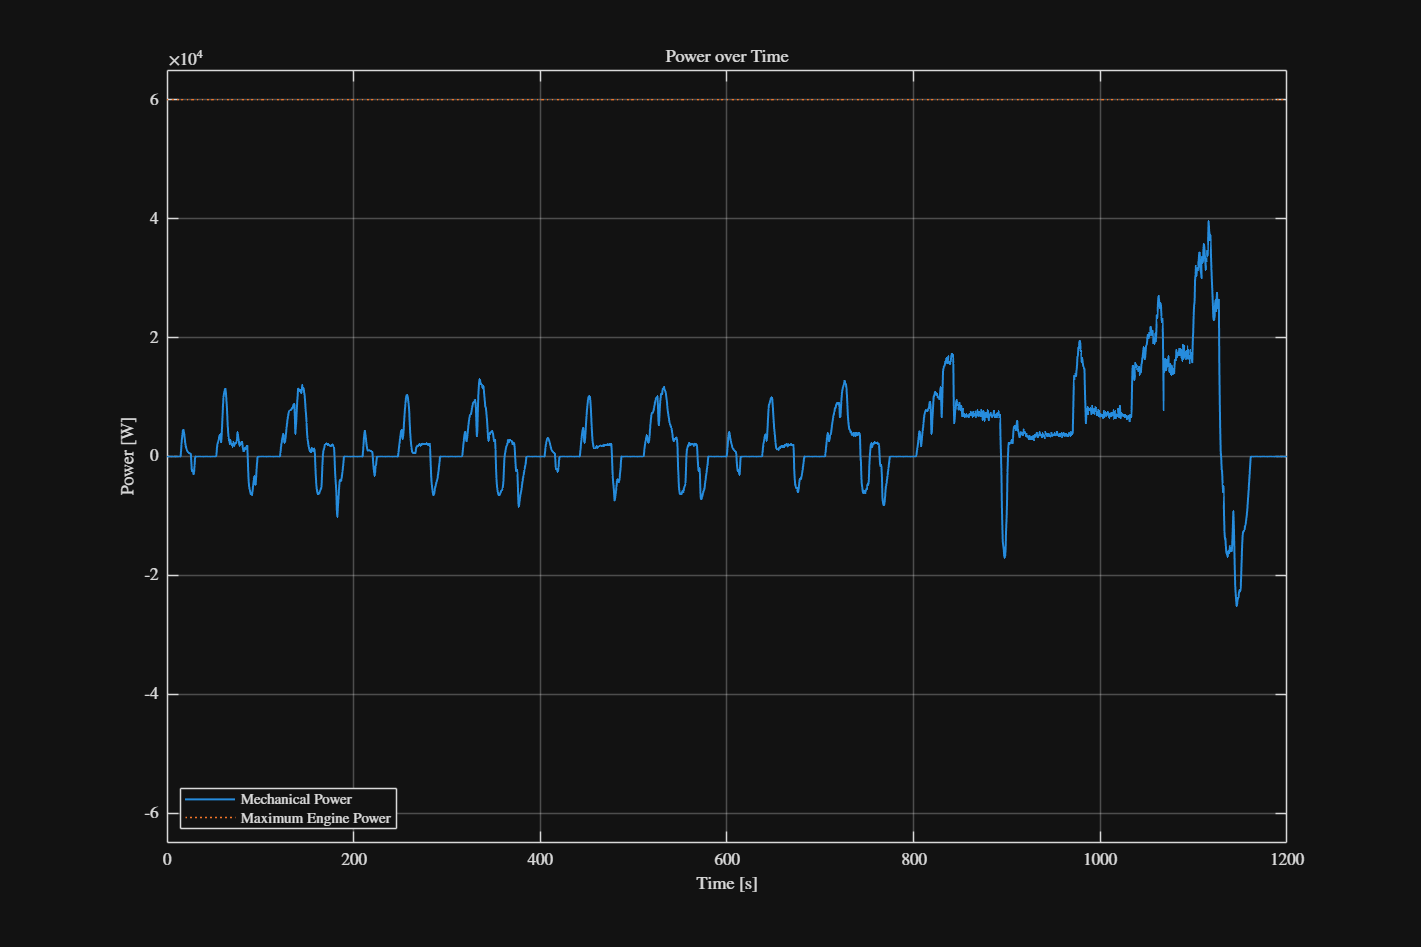

Powermech = dataTable{:,"P_mech[W]"};
Powerenginemax = VEHICLE_PARAMETER.E_MOTOR_POWER.data.value * 1000;
Powerenginemax_vec = ones(size(time)) * Powerenginemax;


figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(1, 1)    

% Mechanical Power
nexttile
plot(time, Powermech, 'LineWidth', 1.2)
line(time, Powerenginemax_vec, 'LineStyle',':')
grid on
xlabel('Time [s]')
ylabel('Power [W]')
title('Power over Time')
ylim([-6.5e4 6.5e4])
legend('Mechanical Power', 'Maximum Engine Power', 'Location','southwest')

In the third plot, the energy demand over time is displayed of every part of the efficiency chain. Additionally, the area between the curves is coloured to better show the losses of every stage. 

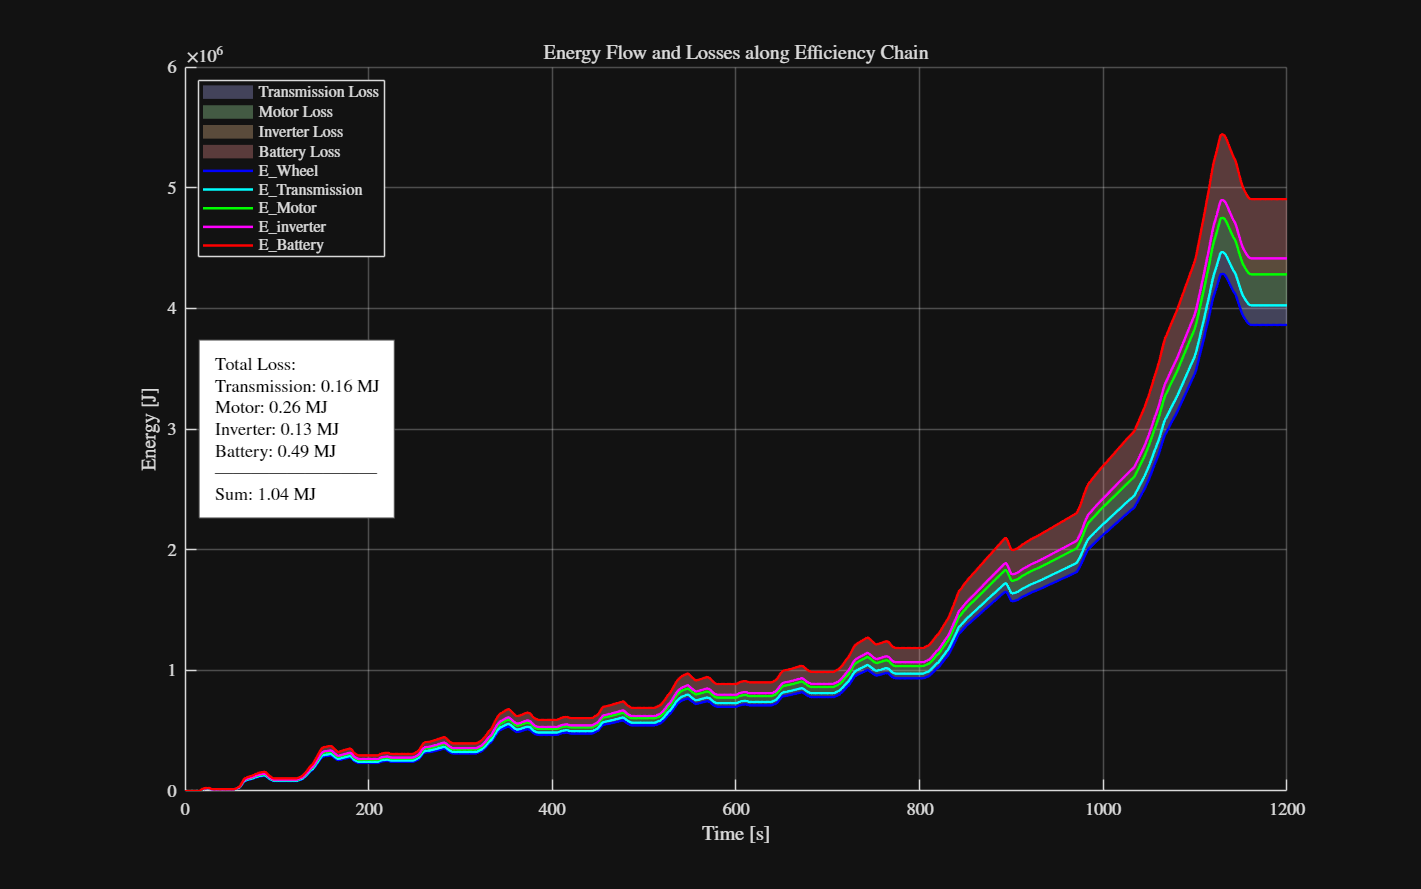

figure('Name', 'Energy Flow in Efficiency Chain', ...
       'NumberTitle', 'off', ...
       'Units', 'normalized', ...    
       'Position', [0.1, 0.1, 0.8, 0.75]);
 
hold on;
fill_between = @(x,y1,y2,c) fill([x; flipud(x)], [y1; flipud(y2)], c, ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
 
 
% filling the areas between the curves to display the losses
fill_between(time, E_Wheel, E_Transmission,    [0.7 0.7 1]); % Transmission Loss
fill_between(time, E_Transmission, E_Motor_in, [0.7 1 0.7]); % Motor Loss
fill_between(time, E_Motor_in, E_Inverter,     [1 0.8 0.6]); % Inverter Loss
fill_between(time, E_Inverter, E_Battery,      [1 0.6 0.6]); % Battery Loss
 
 
% plotting the energy curves
plot(time, E_Wheel,          'b-', 'LineWidth', 1.5);
plot(time, E_Transmission,   'c-', 'LineWidth', 1.5);
plot(time, E_Motor_in,       'g-', 'LineWidth', 1.5);
plot(time, E_Inverter,       'm-', 'LineWidth', 1.5);
plot(time, E_Battery,        'r-', 'LineWidth', 1.5);
 
 
xlabel('Time [s]');
ylabel('Energy [J]');
title('Energy Flow and Losses along Efficiency Chain');
legend({'Transmission Loss','Motor Loss','Inverter Loss','Battery Loss', ...
        'E_Wheel','E_Transmission','E_Motor','E_inverter','E_Battery'}, ...
        'Location', 'northwest');
grid on;

% plotting a text field which displays the complete energy lost at each
% part of the efficiency chain
xPos = mean(xlim) * 0.05;  
yPos = mean(ylim);
 
loss_text = sprintf([ ...
    'Total Loss:\n' ...
    'Transmission: %.2f MJ\n' ...
    'Motor:        %.2f MJ\n' ...
    'Inverter:     %.2f MJ\n' ...
    'Battery:      %.2f MJ\n' ...
    '---------------------------\n' ...
    'Sum:          %.2f MJ'], ...
    E_Loss_Transmission/1e6, ...
    E_Loss_Motor/1e6, ...
    E_Loss_Inverter/1e6, ...
    E_Loss_Battery/1e6, ...
    E_Loss_Total/1e6);

text(xPos, yPos, loss_text, ...
     'Color','k', ...     
     'BackgroundColor',[1 1 1 0.85], ...
     'EdgeColor',[0.4 0.4 0.4], ...
     'Margin',8, ...
     'VerticalAlignment','middle', ...
     'HorizontalAlignment','left');

clearvars -except dataTable VEHICLE_PARAMETER VEHICLE_CHAR EFFICIENCY;

## Correct Energy Flow Direction

Calculating the total equivalent chain efficiency

eta_chain = EFFICIENCY.ETA_TRANS * EFFICIENCY.ETA_MOTOR * EFFICIENCY.ETA_INVERTER * EFFICIENCY.ETA_BATTERY

eta_chain =    787.7952e-003

The recuperated and demanded energies are calculated separately and added as two new columns to the table. The torque sign was used to determine whether the system was in demand, recuperation, or idle mode. 

time  = dataTable{:,"sampling_time[s]"};
torque = dataTable{:,"Torque[Nm]"};
P_mech = dataTable{:,"P_mech[W]"};  

% Efficiencies
eta_chain_motor_to_battery = EFFICIENCY.ETA_MOTOR * EFFICIENCY.ETA_INVERTER * EFFICIENCY.ETA_BATTERY;

P_Demand = zeros(size(P_mech));
P_Recup  = zeros(size(P_mech));

P_Demand(torque > 0) =  P_mech(torque > 0) ./ eta_chain_motor_to_battery;  % power from battery
P_Recup(torque < 0)  = -P_mech(torque < 0) .* eta_chain_motor_to_battery;  % power to battery 

% Integrate over time to get energy
E_Demand = cumtrapz(time, P_Demand);
E_Recup  = cumtrapz(time, P_Recup);

dataTable =  [dataTable, table(E_Demand, VariableNames="E_Demand[J]"), table(E_Recup, VariableNames="E_Recup[J]")]

dataTable = 2401×14 table
    sampling_time[s]    MotorSpeed[rad/s]    Distance[m]    VehicleSpeed[km/h]    Torque[Nm]    MotorSpeed[rpm]    P_mech[W]    E_mech[J]    E_Wheel[J]    E_Motor_in[J]    E_Inverter[J]    E_Battery[J]    E_Demand[J]    E_Recup[J]
    ________________    _________________    ___________    __________________    __________    _______________    _________    _________    __________    _____________    _____________    ____________    ___________    __________
            0                   0   

Calculating the overall energy used and recuperated during the drive cycle

E_total_demand = max(E_Demand);
E_total_recup  = max(E_Recup);
VEHICLE_CHAR.TOTAL_DEMAND.data = struct('value', E_total_demand, 'unit', 'J');
VEHICLE_CHAR.TOTAL_RECUP.data  = struct('value', E_total_recup,  'unit', 'J');


### Money Savings

First the total energy demand &  energy recuperation must be transformed from J to kWh

J_per_kWh = 3.6e6;
E_total_demand_kWh = E_total_demand / J_per_kWh

E_total_demand_kWh =      1.7339e+000

E_total_recup_kWh  = E_total_recup  / J_per_kWh

E_total_recup_kWh =    250.2603e-003

Next, the saved money is being calculated and stored in the data struct

price_AC = 0.30; % €/kWh slow charging
price_DC = 0.40; % €/kWh fast charging

money_saved_AC = E_total_recup_kWh * price_AC

money_saved_AC =     75.0781e-003

money_saved_DC = E_total_recup_kWh * price_DC

money_saved_DC =    100.1041e-003

With fast chraging ~10 Cent are saved and with slow charging 7,5 Cent

VEHICLE_CHAR.MONEY_SAVED_AC.data = struct('value', money_saved_AC, 'unit', '€');
VEHICLE_CHAR.MONEY_SAVED_DC.data = struct('value', money_saved_DC, 'unit', '€');

### SOC Calculation

The vehicle is fully charged at the start of the test

SOC_start = 1; 

Calculation of the SOC

SOC_after_with_recup    = SOC_start - (E_total_demand_kWh - E_total_recup_kWh) / VEHICLE_PARAMETER.BATTERY_CAPACITY.data.value

SOC_after_with_recup =    932.5633e-003

SOC_after_without_recup = SOC_start - E_total_demand_kWh / VEHICLE_PARAMETER.BATTERY_CAPACITY.data.value

SOC_after_without_recup =    921.1878e-003

% storing the results
VEHICLE_CHAR.SOC_WITH_RECUP.data    = struct('value', SOC_after_with_recup * 100,    'unit', '%');
VEHICLE_CHAR.SOC_WITHOUT_RECUP.data = struct('value', SOC_after_without_recup * 100, 'unit', '%');

## Presenting the results

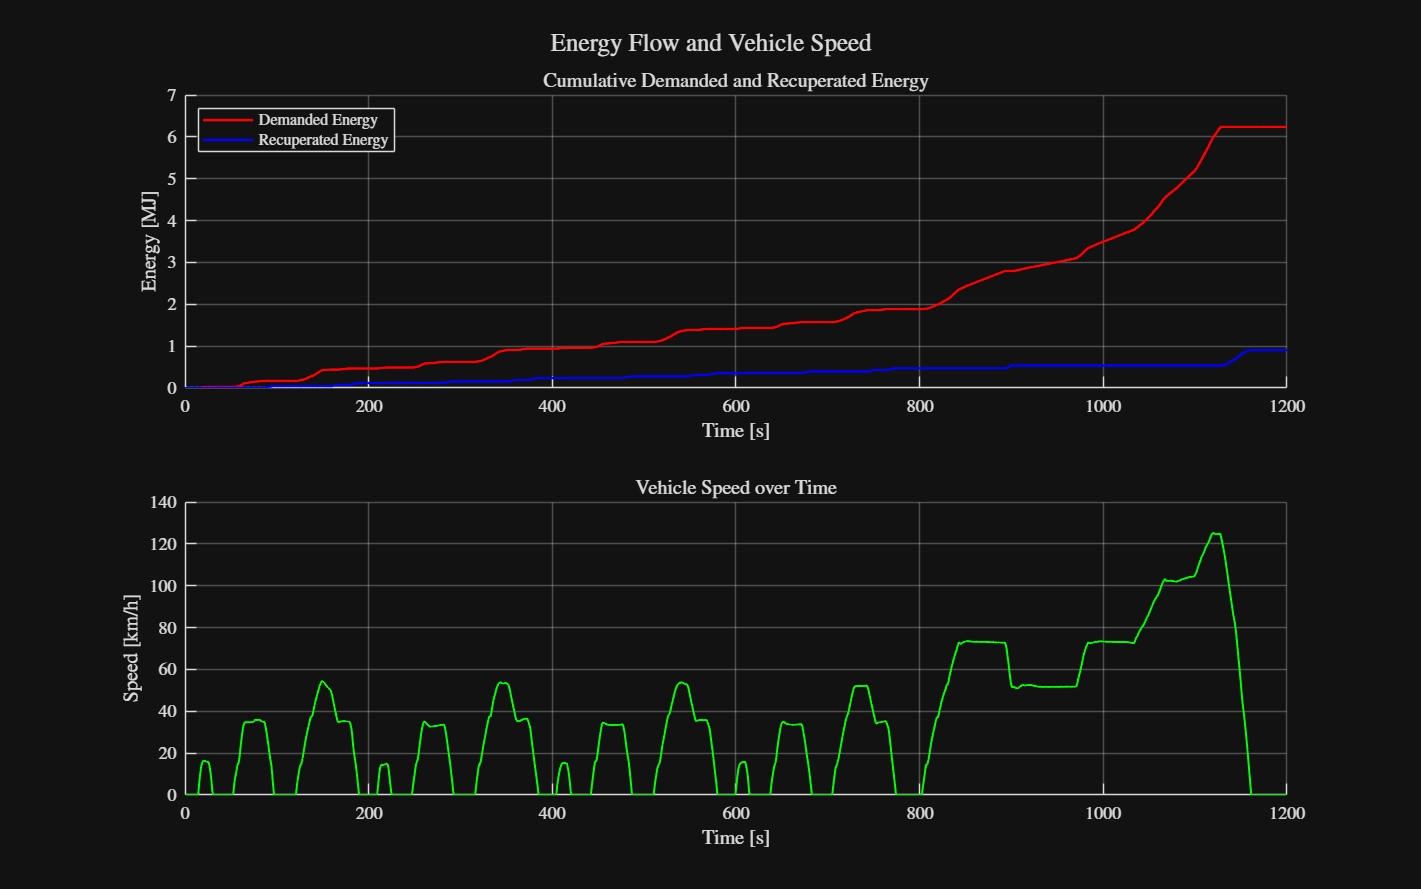

vehicle_speed    = dataTable{:,"VehicleSpeed[km/h]"};


figure('Name','Energy Demand vs Recuperation','NumberTitle','off', ...
       'Units','normalized','Position',[0.1 0.1 0.8 0.75]);

% Subplot 1: demanded and recuperated energy
subplot(2,1,1)
hold on; 
grid on;
plot(time, E_Demand/1e6, 'r-', 'LineWidth', 1.5);   % demanded energy (MJ)
plot(time, E_Recup/1e6,  'b-', 'LineWidth', 1.5);   % recuperated energy (MJ)
xlabel('Time [s]');
ylabel('Energy [MJ]');
title('Cumulative Demanded and Recuperated Energy');
legend({'Demanded Energy','Recuperated Energy'}, 'Location','northwest');
xlim([time(1) time(end)]);

% Subplot 2: vehicle speed
subplot(2,1,2)
hold on; 
grid on;
plot(time, vehicle_speed, 'g-', 'LineWidth', 1.2);
xlabel('Time [s]');
ylabel('Speed [km/h]');
title('Vehicle Speed over Time');
xlim([time(1) time(end)]);

%% --- Improve layout ---
sgtitle('Energy Flow and Vehicle Speed','FontWeight','bold');

Displaying the data structure:

In the data structure all variables calculated can be seen

- mean velocity

- loss of every stage of the efficiency chain

- total loss and total demand / recup

- money saved through recuperation with AC and DC charging

- SOC with and without recuperation

fields = fieldnames(VEHICLE_CHAR);
values = cellfun(@(f) VEHICLE_CHAR.(f).data.value, fields, 'UniformOutput', false);
units  = cellfun(@(f) VEHICLE_CHAR.(f).data.unit, fields, 'UniformOutput', false);

VehicleCharTable = table(fields, values, units, ...
    'VariableNames', {'Parameter','Value','Unit'});

VehicleCharTable 

VehicleCharTable = 12×3 table
          Parameter                Value            Unit  
    _____________________    _________________    ________
    {'MEAN_VEL'         }    {[ 34.1392e+000]}    {'km/h'}
    {'BATTERY_LOSS'     }    {[490.4064e+003]}    {'J'   }
    {'INVERTER_LOSS'    }    {[132.4097e+003]}    {'J'   }
    {'MOTOR_LOSS'       }    {[256.8749e+003]}    {'J'   }
    {'TRANSMISSION_LOSS'}    {[160.9749e+003]}    {'J'   }
    {'TOTAL_LOSS'       }    {[  1.0407e+006]}    {'J'   }
    {'TOTAL_DEMAND'     }    {[  6.2419e+006]}    {'J'   }
    {'TOTAL_RECUP'      }    {[900.9370e+003]}    {'J'   }
    {'MONEY_SAVED_AC'   }    {[ 75.0781e-003]}    {'€'   }
    {'MONEY_SAVED_DC'   }    {[100.1041e-003]}    {'€'   }
    {'SOC_WITH_RECUP'   }    {[ 93.2563e+000]}    {'%'   }
    {'SOC_WITHOUT_RECUP'}    {[ 92.1188e+000]}    {'%'   }

clearvars -except dataTable VEHICLE_PARAMETER VEHICLE_CHAR EFFICIENCY;
